# RKKY 相互作用

[什么是量子磁性中的 RKKY 相互作用？ - 知乎](https://www.zhihu.com/question/37103464/answer/1950779627)


clear;
t = 1;
e0 = 2;
state = 2;
num = 501;
omega = linspace(-0.1, 2, num);

s0 = eye(state);
sz = [1,0;0,-1];

H00 = e0 * s0;
H01 = -t * s0;
H10 = H01';
% 重现震荡需要调节无穷小虚部
eta = 0.8*1i*1e-2;

Length = 1:51;
J = zeros(length(omega), length(Length));
Iteration = 100;
for jj = 1: length(Length)
    for ii = 1:length(omega)
        SurfaceGF = SurfaceGreenFunction(H00, H01, omega(ii)+eta, Iteration);
        Sigma_L = SurfaceGreenFunction_SelfEnergy(SurfaceGF, H01);
        Sigma_R = SurfaceGreenFunction_SelfEnergy(SurfaceGF, H01');
        G_Centre_Ret = SurfaceGreenFunction_Gcc_1L(H00, H01, Length(jj), omega(ii), Sigma_L, Sigma_R, eta);
        J(ii, jj) = (-1/pi) * imag(trace(sz*G_Centre_Ret*sz*G_Centre_Ret));
    end
end

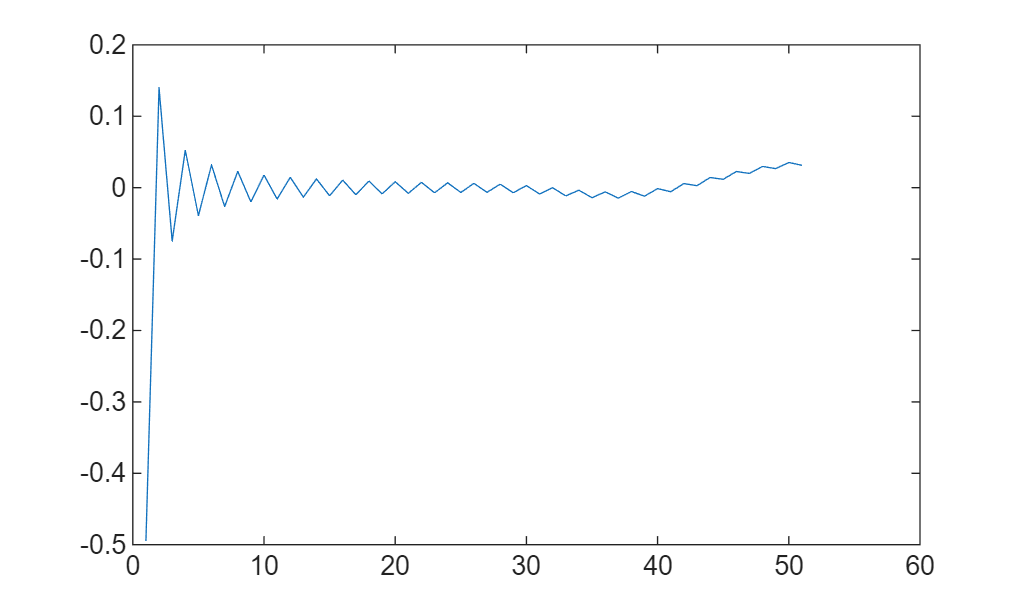

J_Len = trapz(omega, J, 1);
plot(Length, J_Len)